clear all;
%close all;

% Nx = 100;
% Ny = 100;
% tmax = 300;
% Nt = 300;

% h = 1;
% dt = tmax / Nt

Nx=100;
Ny=Nx;
tmin=0;
tmax=3;

xmin=-0.5;
xmax=0.5;
% h=(xmax-xmin)/Nx
x=linspace(xmin,xmax,Nx);
h=x(2)-x(1)

h = 0.0101


ymin=-0.5;
ymax=0.5;
% h=(xmax-xmin)/Nx
y=linspace(ymin,ymax,Ny);
% h=x(2)-x(1)




dt=0.5*h;
Nt=round(tmax/dt);
% dt=tmax/N
% dt/h

t=linspace(tmin,tmax,Nt);
dt=t(2)-t(1)

dt = 0.0051

dt_over_h=dt/h

dt_over_h = 0.5008



% xrange = h * ((1:Nx) - Nx/2);
% yrange = h * ((1:Ny)' - Ny/2);

% p_now = cos(pi*y')*cos(pi*x);
% p_now = cos(3*pi*y')*cos(pi*x);
p_now = exp(-50*(x.^2+y'.^2));
% p_now = exp(-200*(x.^2+y'.^2));

p_past = p_now;





% coarse square 
% boundary = [...
%     0 0 0 0 1 1 0 0 0 0;
%     0 0 0 1 1 1 1 0 0 0;
%     0 0 1 1 1 1 1 1 0 0;
%     0 1 1 1 1 1 1 1 1 0;
%     1 1 1 1 1 1 1 1 1 1;
%     1 1 1 1 1 1 1 1 1 1;
%     0 1 1 1 1 1 1 1 1 0;
%     0 0 1 1 1 1 1 1 0 0;
%     0 0 0 1 1 1 1 0 0 0;
%     0 0 0 0 1 1 0 0 0 0];

% Coarse guitar shape
boundary = [...
    0 0 1 0 0 1 1 0 0 0;
    0 1 1 0 0 1 1 1 0 0;
    0 1 1 1 1 1 1 1 0 0;
    0 0 1 1 1 1 1 1 1 0;
    0 0 0 1 1 1 1 1 1 0;
    0 0 0 1 1 1 1 1 0 0;
    0 0 1 1 1 1 1 0 0 0;
    0 0 1 1 1 1 1 1 1 0;
    0 0 0 1 1 1 1 1 0 0;
    0 0 0 0 1 1 1 0 0 0];

% Coarse T shape
% boundary = [...
%     0 0 0 1 1 1 1 0 0 0;
%     0 0 0 1 1 1 1 0 0 0;
%     0 0 0 1 1 1 1 0 0 0;
%     0 0 0 1 1 1 1 0 0 0;
%     0 0 0 1 1 1 1 0 0 0;
%     0 0 0 1 1 1 1 0 0 0;
%     0 0 0 1 1 1 1 0 0 0;
%     1 1 1 1 1 1 1 1 1 1;
%     1 1 1 1 1 1 1 1 1 1;
%     1 1 1 1 1 1 1 1 1 1];

multiplier = Nx/10;
boundary= kron(boundary ,ones(multiplier));



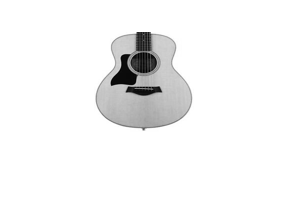

% Create a Guitar shape boundary

guitar_rgb=imread('guitar_shape.jpg');
guitar_grey = rgb2gray(guitar_rgb);
guitar_grey=guitar_grey(50:300,:); % Adjust zoom/size to that of guitar
guitar_resize = imresize(guitar_grey, [Nx, Nx]);
imshow(guitar_resize)

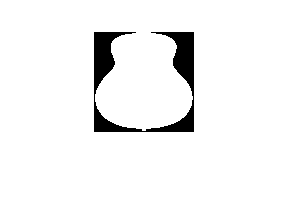

grey_threshold=240/255;
guitar_shape_01 = imadjust(guitar_resize, [grey_threshold grey_threshold+0.0001], [1 0]);
imshow(guitar_shape_01)

boundary= rescale(guitar_shape_01,0,1);
boundary(1,:)=zeros([1 size(boundary,2)])

boundary =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

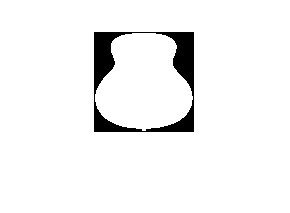

imshow(boundary)


save('guitar_object.mat','boundary')

load('guitar_object.mat')

Nframes=100

Nframes = 100

frame_nr = 1

frame_nr = 1

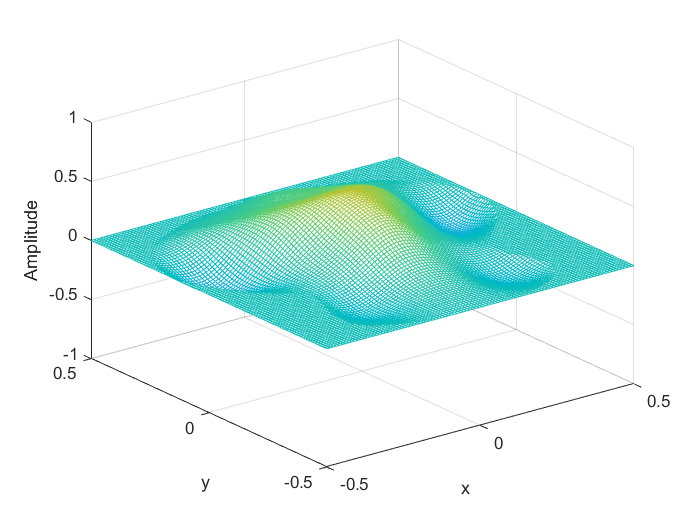

% frame_nr = 0;
for t_idx = 1:Nt
  t = dt * t_idx;
    
  pdx=diff(p_now,2,2);
  pdy=diff(p_now,2,1);
  pdtot=pdx(2:end-1,:)+pdy(:,2:end-1);
  
  p_new = 2 * p_now(2:end-1,2:end-1) - p_past(2:end-1,2:end-1) + (dt/h)^2 * pdtot;
  p_past = p_now;
  p_now(2:end-1,2:end-1) = p_new;
  
  p_now=p_now.*boundary; 
  
%   if frame_nr <= t*10
  if frame_nr <= t_idx/Nt*Nframes
    frame_nr = frame_nr + 1;
    
    % 3D mesh plot
    mesh(x, y, p_now);
    axis([xmin, xmax, ymin, ymax -1, 1]);
    caxis([-1, 1]);
    zlabel('Amplitude')
    
%     %2D colormap
%     pcolor(x,y,p_now)
%     cbar=colorbar;
%     ylabel(cbar,'Amplitude','FontSize',16);
%     caxis([-1, 1]);
    
    
    xlabel('x')
    ylabel('y')
    pause(0.0001);
    drawnow;
  end
end